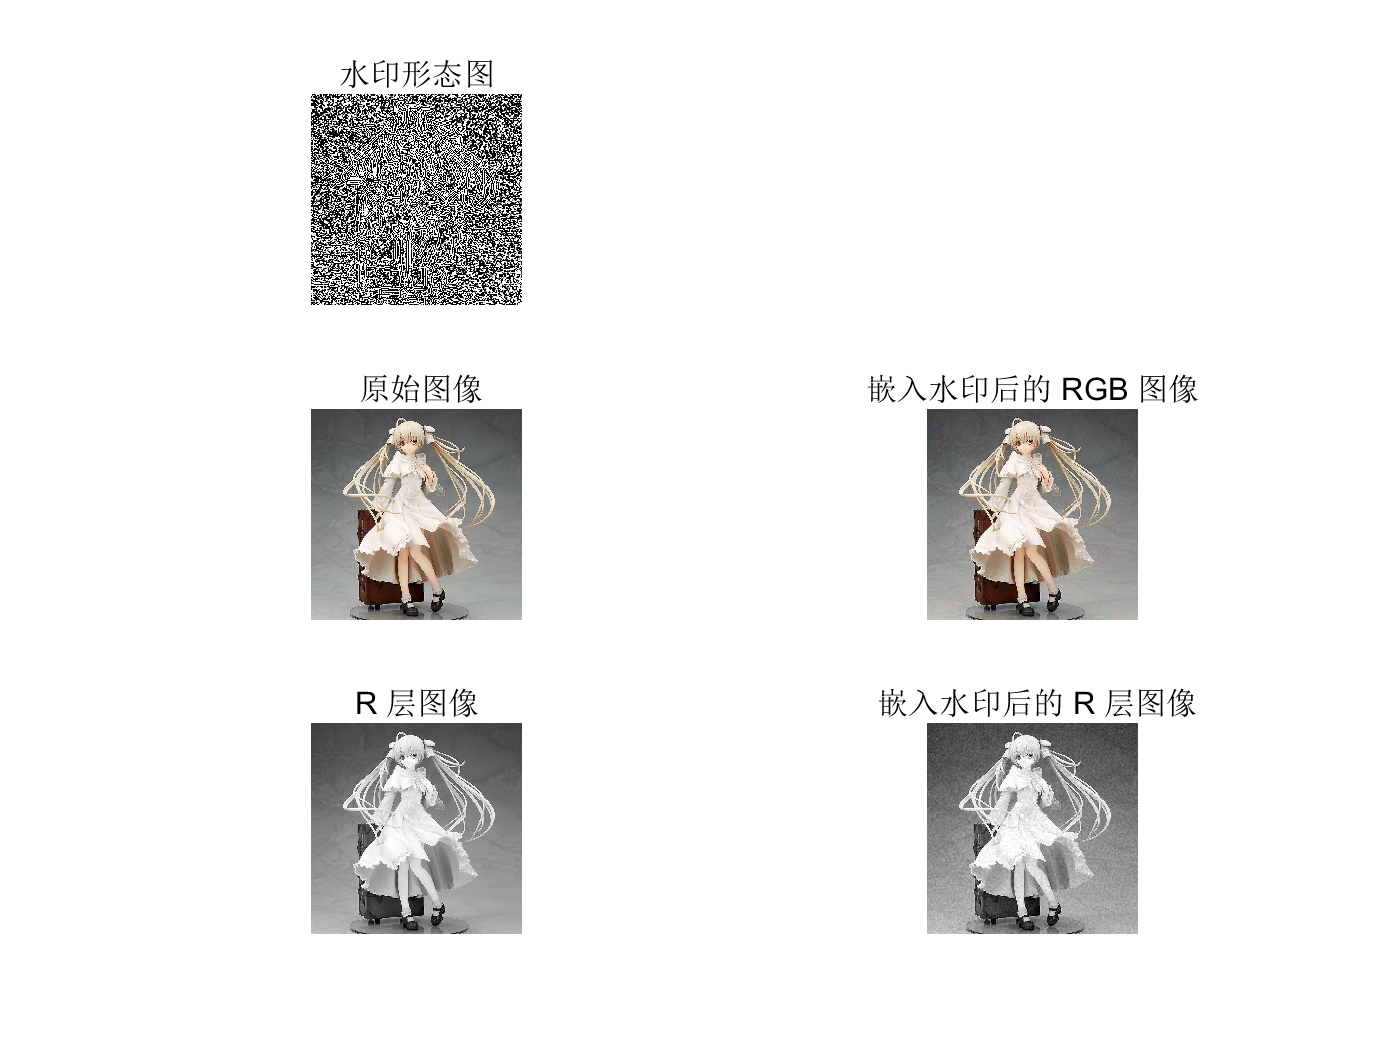

images = {'test_qm_NOISE_0.bmp', 'test_qm_NOISE_20.bmp', 'test_qm_NOISE_40.bmp', 'test_qm_NOISE_60.bmp', 'test_qm_NOISE_80.bmp'};
corr_Wcoef = zeros(5, 1) ;
corr_Dcoef = zeros(5, 1) ;
for i = 1 : 5
    [corr_coef, corr_DCTcoef] = wavedetect(string(images(i)), 'qm.jpg', 10, 'db6', 2, 0.5, 0.99);
    corr_Wcoef(i) = corr_coef;
    corr_Dcoef(i) = corr_DCTcoef;
end

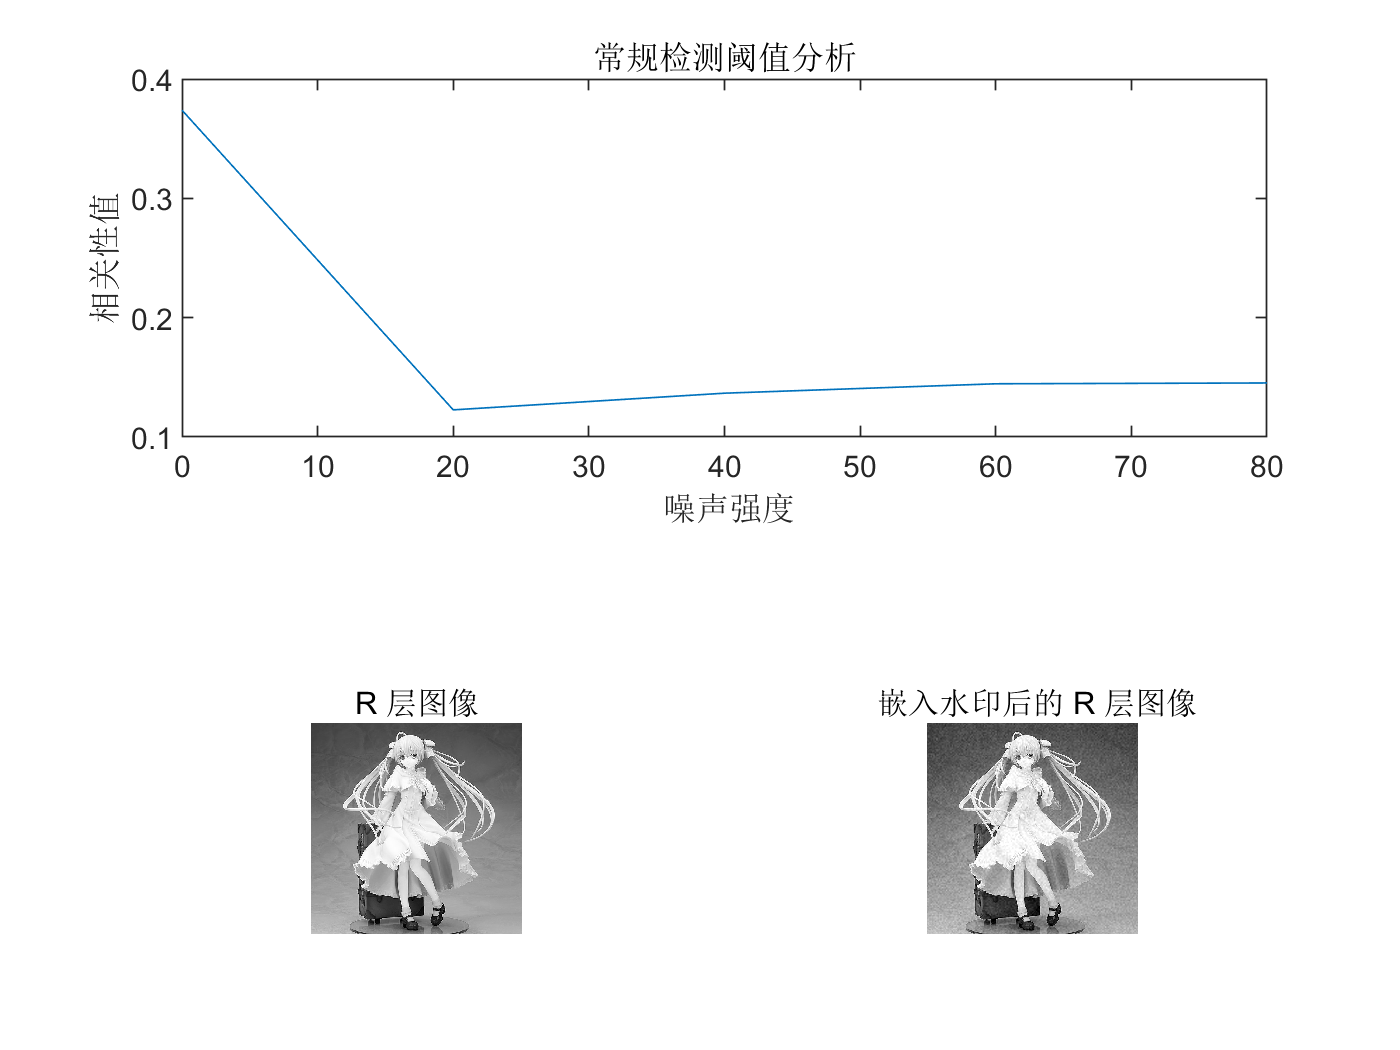


subplot( 211) ; 
plot([0, 20, 40, 60, 80], abs( corr_Wcoef) ) ; 
title( '常规检测阈值分析' ) ; 
xlabel( ' 噪声强度' ) ; 
ylabel( '相关性值' ) ; 

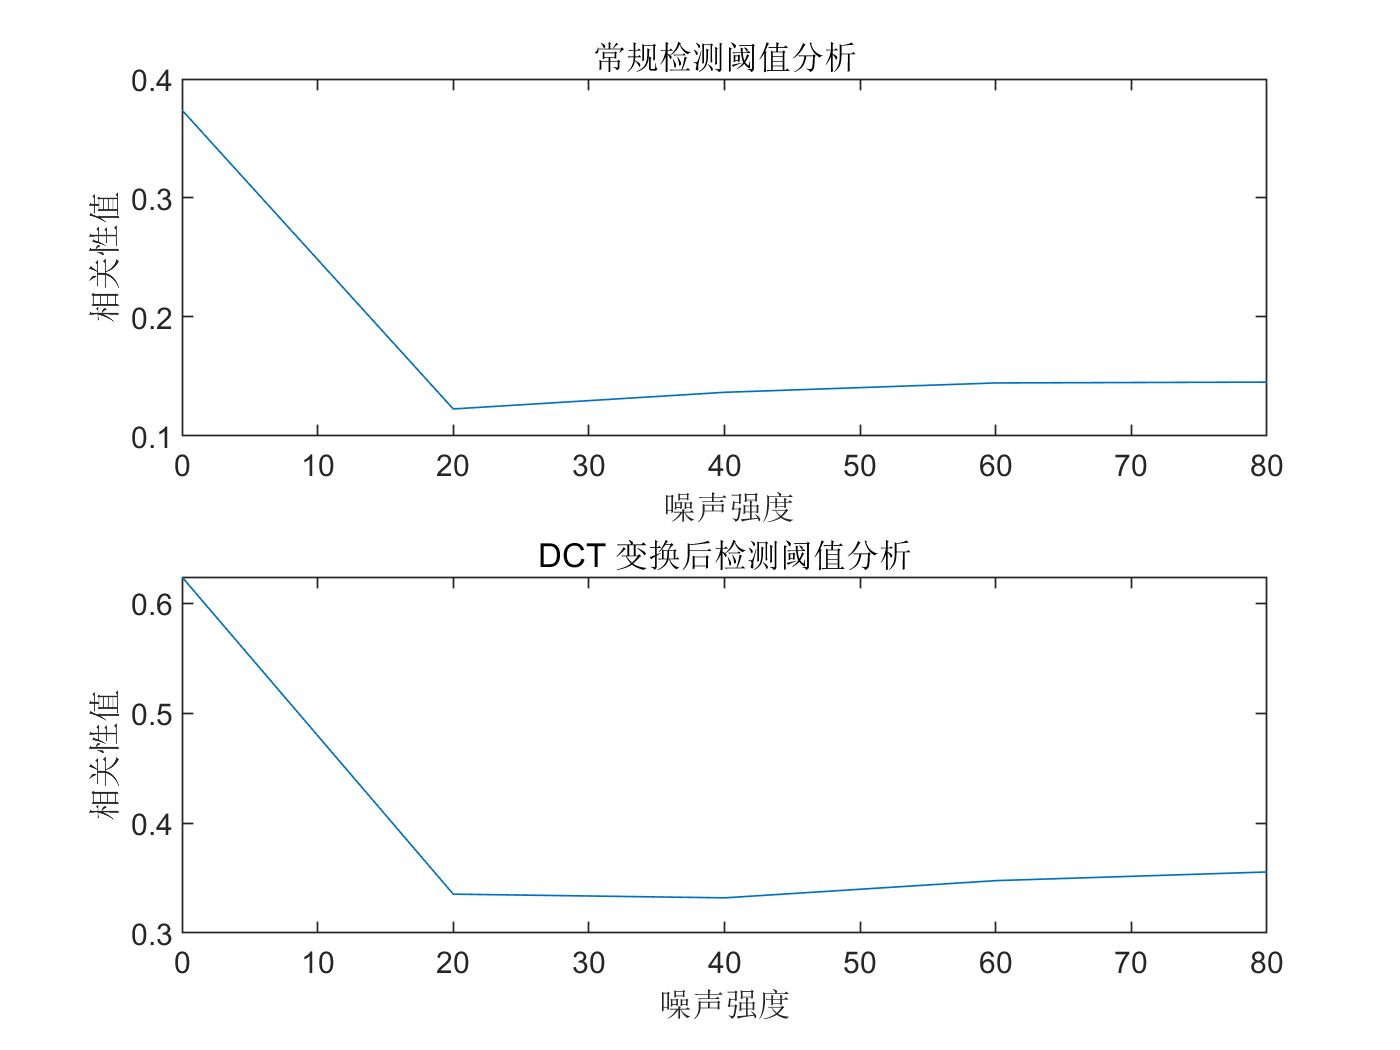

subplot( 212) ; plot([0, 20, 40, 60 ,80], abs( corr_Dcoef) ) ; 
%待测 
title( 'DCT 变换后检测阈值分析' ) ; 
xlabel( '噪声强度' ) ;
ylabel( '相关性值' ) ;